# Damped Harmonic Motion

## Task 1

This activity will guide you through obtaining the solution matrix for the following system of first-order ODEs.

dydt=v

dvdt=−bmv−kmy

where m=0.05 kg, b=0.5kg/s, and k=50 N/m.

The spring is initially stretched 0.1m away from its unstretched length and the block is released from rest at that position. 

Task

The ODE function `harmonicMotion` has been written for you at the bottom of the script to the right. Solve the system of ODEs by following these steps:

1. Set the time interval `tRange` to span from 0 to 1 seconds. 

2. Define the column vector of initial conditions and store them in an array `Y0`. 

3. Obtain the solution matrix `YSol` and `tSol` using `ode45`. 

tRange=[0 1]

tRange =      0     1


Y0=[0.1;0]

Y0 =     0.1000
         0


[tSol,YSol]=ode45(@harmonicMotion,tRange,Y0)

tSol =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


YSol =     0.1000         0
    0.1000   -0.0001
    0.1000   -0.0001
    0.1000   -0.0002
    0.1000   -0.0002
    0.1000   -0.0005
    0.1000   -0.0007
    0.1000   -0.0010
    0.1000   -0.0012
    0.1000   -0.0025


## Task 2

Extract the position of the mass from the first column of `YSol` and store it in a variable `y` then plot `y` versus `tSol`.

y=YSol(:,1)

y =     0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000


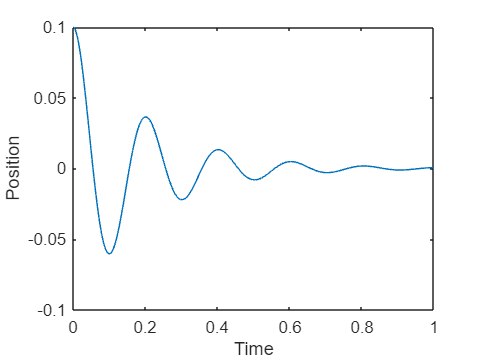

plot(tSol,y)
% Label axes
xlabel("Time")
ylabel("Position")

## Task 3

Extract the velocity of the mass from the second column of `YSol` and store it in a variable `v` then plot `v` versus `tSol`.

v=YSol(:,2)

v =          0
   -0.0001
   -0.0001
   -0.0002
   -0.0002
   -0.0005
   -0.0007
   -0.0010
   -0.0012
   -0.0025


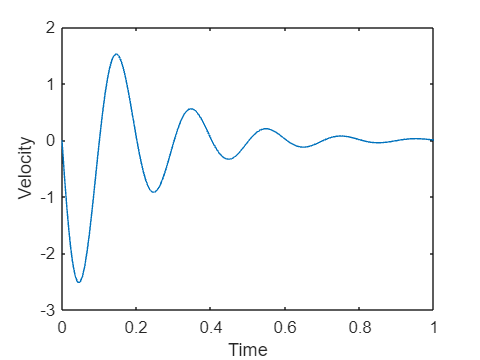

plot(tSol,v)

% Label axes
xlabel("Time")
ylabel("Velocity")

## Further Practice

Remember that the derivative of a function represents the slope or rate  at which a function changes. Try investigating the two plots that you  have created.

You can click on any point in the graphs to view  the x- and y-values of that point. Do the velocity values seem to  correspond to how the position function is changing? For example, when  the position is decreasing, is the velocity negative?

## ODE function

Do not edit. This code defines the ODE function for the system of ODEs.

function dYdt = harmonicMotion(t,Y)

%Define constants k, m, and b
k = 50;
m = 0.05;
b = 0.5;

% TODO - Extract the position x from the first element of Y.
y = Y(1);

% TODO - Extract the velocity v from the second element of Y.
v = Y(2);

% TODO - Complete expression for dxdt
dxdt = v;

% TODO - Complete expression for dvdt
dvdt = -(k/m)*y - (b/m)*v;

% TODO - Create dYdt, column vector containing dxdt, and dvdt
dYdt = [dxdt;dvdt];

end